% This script performs PCA on EEG data to compare P1 and P2 on time windown of 0 to 2400
clear;
close all;

%% Set paths based on available drives
if exist('H:\', 'dir')  % Computer 1
    input_base_path = 'H:\My Drive\Data\New Data\EEG epoched';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')  % Computer 2
    input_base_path = 'G:\My Drive\Data\New Data\EEG epoched';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

%% Define analysis parameters
% Define conditions, subjects and channels
conditions = {'P1', 'P2', 'P3'};
subjects = {'BOS2'};%, 'BOS3', 'BOS5', 'BOS6', 'BOS7', 'BOS8', 'BOS9', 'BOS10', ...
    % 'BOS11', 'BOS12', 'BOS13', 'BOS15', 'BOS16', 'BOS17'
channels = {'F3'};% , 'C3'
analysis = {'temporal','stimulus'}; % the type of uncertainty we are looking for temporal or stimulus
% Define number of PCs to extract
num_pcs = 32;

% Create output directory
output_path_perChannel = fullfile(output_path, 'pca_per_channel', 'temporal_uncertainty');
if ~exist(output_path_perChannel, 'dir')
    mkdir(output_path_perChannel);
end

## Initialize structures for plotting

% We'll store PC results for each filtering type, condition, and channel
all_results = struct();

% Create a cell array to store all subject data for later combining
subject_data_cell = cell(length(subjects), 1); 

for subj_idx = 1:length(subjects)
    subject = subjects{subj_idx};
    all_results.(subject) = struct();
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        all_results.(subject).(channel) = struct();
        all_results.(subject).(channel).unfiltered = [];
        all_results.(subject).(channel).beta = struct();
        all_results.(subject).(channel).beta.temporal =struct();
        all_results.(subject).(channel).beta.temporal.signal = [];
        all_results.(subject).(channel).beta.temporal.time_points = [];
        all_results.(subject).(channel).beta.temporal.coeff = [];
        all_results.(subject).(channel).beta.temporal.score = [];
        all_results.(subject).(channel).beta.temporal.explained = [];
        all_results.(subject).(channel).beta.stimulus =struct();
        all_results.(subject).(channel).beta.stimulus.signal = [];
        all_results.(subject).(channel).beta.stimulus.time_points = [];
        all_results.(subject).(channel).beta.stimulus.coeff = [];
        all_results.(subject).(channel).beta.stimulus.score = [];
        all_results.(subject).(channel).beta.stimulus.explained = [];
    end
end

## Main Analysis Loop

% Loop over subjects
for subj_idx = 1:length(subjects)
    subject = subjects{subj_idx};
    fprintf('Processing condition: %s\n', subject);
    
    % Process each channel
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        disp(['    Processing channel: ', channel]);

        for cond_idx = 1:length(conditions)
            condition = conditions{cond_idx};
            fprintf('Processing condition: %s\n', condition);
            % Set condition-specific paths
            condition_input_path = fullfile(input_base_path, condition);
            condition_output_path = fullfile(output_path_perChannel, subject);
            
            % Create output directory if it doesn't exist
            if ~exist(condition_output_path, 'dir')
                mkdir(condition_output_path);
            end
             % Set excel file path for P2 and P3 conditions if needed
            if strcmp(condition, 'P2')
                excel_file_path = fullfile(input_base_path, 'Indexes for P2.xlsx');
            elseif strcmp(condition, 'P3')
                excel_file_path = fullfile(input_base_path, 'Indexes for P3.xlsx');
            else
                excel_file_path = '';
            end
            
            % Get all .set files in the directory
            set_files = dir(fullfile(condition_input_path, '*.set'));
            file_idx = find_subject_file(set_files, subject);
            if file_idx == 0
                warning('No matching file found for subject %s in condition %s. Skipping.', subject, condition);
                subject_data_cell{sub_idx} = local_subject_data_trials.trials; % Store empty trial-dim result
                continue;
            end
            file_idx = find_subject_file(set_files, subject);
            file_path = fullfile(condition_input_path, set_files(file_idx).name);
            disp(['    Using file: ', set_files(file_idx).name]);
                    
            EEG = pop_loadset(file_path);
    
            % Extract relevant parameters
            fs = EEG.srate; % Sampling rate
            time_vector = EEG.times/1000;
            epoch_trials = 1:2:EEG.trials; % Odd epochs for conditions P1, P2 and P3
            num_trials = length(epoch_trials);
    
            % Determine valid trials for this subject based on condition and excel files
            current_subject_valid_trials = epoch_trials; % Start with all trials for this subject
            if strcmp(condition, 'P2')
                trials_500ms_sheet = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
                trials_2000ms_sheet = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
                % Filter sheet trials by those present in this subject's EEG.epoch.eventtrial
                subject_specific_500ms = intersect(epoch_trials, trials_500ms_sheet);
                subject_specific_2000ms = intersect(epoch_trials, trials_2000ms_sheet);
                current_subject_valid_trials = unique([subject_specific_500ms; subject_specific_2000ms]);
            elseif strcmp(condition, 'P3')
                trials_500ms_sheet = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
                trials_missing_sheet = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
                subject_specific_500ms = intersect(epoch_trials, trials_500ms_sheet);
                subject_specific_missing = intersect(epoch_trials, trials_missing_sheet);
                current_subject_valid_trials = unique([subject_specific_500ms; subject_specific_missing]);
            end

       
            post_window_temporal = [0, 2.400];
            post_idx_temporal = find(time_vector >= post_window_temporal(1) & time_vector <= post_window_temporal(2));
            post_window_stimulus = [0, 2.400];% 1.020
            post_idx_stimulus = find(time_vector >= post_window_stimulus(1) & time_vector <= post_window_stimulus(2));

            channel_idx_eeg = find(strcmp({EEG.chanlocs.labels}, channel));
            if isempty(channel_idx_eeg)
                warning('Channel %s not found in EEG data for subject %s. Skipping.', channel, subject);
                continue;
            end
            if strcmp(condition, 'P1')
                subject_channel_p1_temopral_data = EEG.data(channel_idx_eeg, post_idx_temporal, current_subject_valid_trials(1:30));% Channel x Time x SubjectValidTrials
                subject_channel_p1_stimulus_data = EEG.data(channel_idx_eeg, post_idx_stimulus, current_subject_valid_trials(1:30));
                %TODO: reshape the data before concatenation
                subject_channel_p1_temopral_data_reshaped = reshape(subject_channel_p1_temopral_data,size(subject_channel_p1_temopral_data, 2), size(subject_channel_p1_temopral_data,3));
                subject_channel_p1_stimulus_data_reshaped = reshape(subject_channel_p1_stimulus_data,size(subject_channel_p1_stimulus_data, 2), size(subject_channel_p1_stimulus_data,3));
            elseif strcmp(condition, 'P2')
                subject_channel_p2_500_data = EEG.data(channel_idx_eeg, post_idx_temporal, subject_specific_500ms);
                subject_channel_p2_2000_data = EEG.data(channel_idx_eeg, post_idx_temporal, subject_specific_2000ms);
                subject_channel_p2_500_data_reshape = reshape(subject_channel_p2_500_data, size(subject_channel_p2_500_data,2), size(subject_channel_p2_500_data,3));
                subject_channel_p2_2000_data_reshape = reshape(subject_channel_p2_2000_data, size(subject_channel_p2_2000_data,2), size(subject_channel_p2_2000_data,3));
            elseif strcmp(condition, 'P3')
                subject_channel_p3_500_data = EEG.data(channel_idx_eeg, post_idx_stimulus, subject_specific_500ms);
                subject_channel_p3_missing_data = EEG.data(channel_idx_eeg, post_idx_stimulus, subject_specific_missing);
                subject_channel_p3_500_data_reshape = reshape(subject_channel_p3_500_data, size(subject_channel_p3_500_data, 2), size(subject_channel_p3_500_data,3));
                subject_channel_p3_missing_data_reshape = reshape(subject_channel_p3_missing_data, size(subject_channel_p3_missing_data, 2), size(subject_channel_p3_missing_data,3));
            end     
        end


        subject_channel_temporal_data = [subject_channel_p1_temopral_data_reshaped,subject_channel_p2_500_data_reshape, subject_channel_p2_2000_data_reshape];
        subject_channel_stimulus_data = [subject_channel_p1_stimulus_data_reshaped,subject_channel_p3_500_data_reshape, subject_channel_p3_missing_data_reshape];
    
        % Bandpass filter beta band (13-30 Hz)
        beta_band = [13 30];
        subject_channel_temporal_beta_signal = zeros(size(subject_channel_temporal_data)); % Preallocate
        subject_channel_stimulus_beta_signal = zeros(size(subject_channel_stimulus_data));
        for tr = 1:size(subject_channel_temporal_data, 2)
            subject_channel_temporal_beta_signal(:,tr) = bandpass(subject_channel_temporal_data(:,tr), beta_band, fs);
            subject_channel_stimulus_beta_signal(:,tr) = bandpass(subject_channel_stimulus_data(:,tr), beta_band, fs);
        end
        all_results.(subject).(channel).beta.temporal.signal = subject_channel_temporal_beta_signal;
        all_results.(subject).(channel).beta.stimulus.signal = subject_channel_stimulus_beta_signal;
        
        % Now perform PCA on the combined data for each channel and filtering method
        [coeff_temporal_beta, score_temporal_beta, ~, ~, explained_temporal_beta] = pca(all_results.(subject).(channel).beta.temporal.signal);
        [coeff_stimulus_beta, score_stimulus_beta, ~, ~, explained_stimulus_beta] = pca(all_results.(subject).(channel).beta.stimulus.signal);
        
        all_results.(subject).(channel).beta.temporal.time_points = time_vector(post_idx_temporal);
        all_results.(subject).(channel).beta.temporal.coeff = coeff_temporal_beta;
        all_results.(subject).(channel).beta.temporal.score = score_temporal_beta;
        all_results.(subject).(channel).beta.temporal.explained = explained_temporal_beta;
        all_results.(subject).(channel).beta.stimulus.time_points = time_vector(post_idx_stimulus);
        all_results.(subject).(channel).beta.stimulus.coeff = coeff_stimulus_beta;
        all_results.(subject).(channel).beta.stimulus.score = score_stimulus_beta;
        all_results.(subject).(channel).beta.stimulus.explained = explained_stimulus_beta;
        % Save PCA results
        save(fullfile(condition_output_path, [channel '_pca_results.mat']),'all_results');
        

    end
            
end

Processing condition: BOS2


    Processing channel: F3


Processing condition: P1


    Using file: binepochs filtered ICArej P1AvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Processing condition: P2


    Using file: binepochs filtered ICArej P2AvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Processing condition: P3


    Using file: binepochs filtered ICArej P3AvgBOS2.set


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


%TODO: add loops to combine subjects data


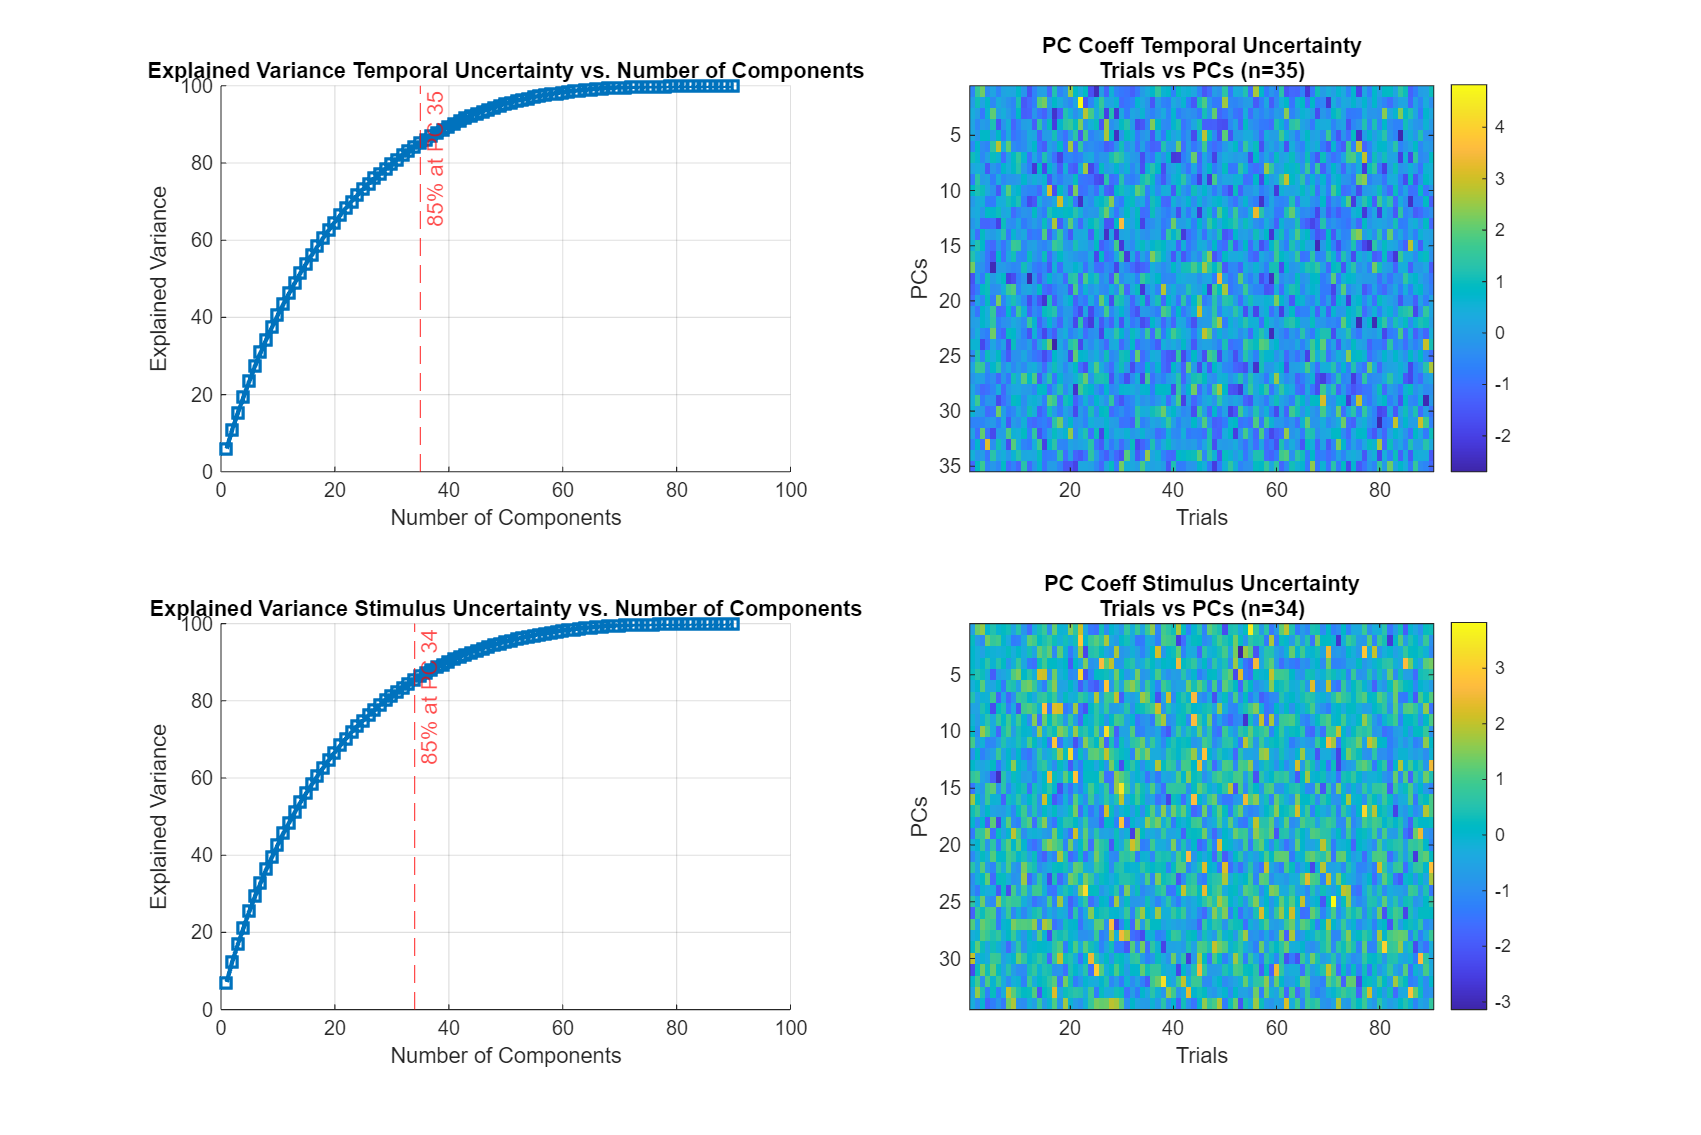

% Plot results
% Loop over subjects
for subj_idx = 1:length(subjects)
    subject = subjects{subj_idx};
     % Process each channel
    for ch_idx = 1:length(channels)
        channel = channels{ch_idx};
        
        explained_temporal = all_results.(subject).(channel).beta.temporal.explained;
        coeff_temporal = all_results.(subject).(channel).beta.temporal.coeff;
        coeff_temporal_z = zscore(coeff_temporal);
        explained_stimulus = all_results.(subject).(channel).beta.stimulus.explained;
        coeff_stimulus = all_results.(subject).(channel).beta.stimulus.coeff;
        coeff_stimulus_z = zscore(coeff_stimulus );

        % Find how many PCs are needed to explain 85% variance
        cum_explained_temporal = cumsum(explained_temporal);
        num_pcs_85percent_temporal = find(cum_explained_temporal >= 85, 1, 'first');
        cum_explained_stimulus = cumsum(explained_stimulus);
        num_pcs_85percent_stimulus = find(cum_explained_stimulus >= 85, 1, 'first');

        figure('Name', ['PCA - ' subject ' - Channel ' channel], ...
            'Position', [100, 100, 1500, 1000]); % [x, y, width, height]

        subplot(2,2,1)
        hold on;
        plot(1:length(cum_explained_temporal),cum_explained_temporal , 's-', 'LineWidth', 2);
        xline(num_pcs_85percent_temporal, '--r', ['85% at PC ' num2str(num_pcs_85percent_temporal)]);
        xlabel('Number of Components');
        ylabel('Explained Variance');
        title('Explained Variance Temporal Uncertainty vs. Number of Components');
        grid on;
        hold off; 
        
        subplot(2,2,2)
        imagesc(coeff_temporal_z(:,1:num_pcs_85percent_temporal)');
        title({'PC Coeff Temporal Uncertainty'; ['Trials vs PCs (n=' num2str(num_pcs_85percent_temporal) ')']});
        xlabel('Trials'); ylabel('PCs'); colorbar;

        subplot(2,2,3)
        hold on;
        plot(1:length(cum_explained_stimulus),cum_explained_stimulus , 's-', 'LineWidth', 2);
        xline(num_pcs_85percent_stimulus, '--r', ['85% at PC ' num2str(num_pcs_85percent_stimulus)]);
        xlabel('Number of Components');
        ylabel('Explained Variance');
        title('Explained Variance Stimulus Uncertainty vs. Number of Components');
        grid on;
        hold off; 
        
        subplot(2,2,4)
        imagesc(coeff_stimulus_z(:,1:num_pcs_85percent_stimulus)');
        title({'PC Coeff Stimulus Uncertainty'; ['Trials vs PCs (n=' num2str(num_pcs_85percent_stimulus) ')']});
        xlabel('Trials'); ylabel('PCs'); colorbar;
        saveas(gcf, fullfile(output_path_perChannel, ['TrialPCA_uncertainty_Channel_' channel '.fig']));
        saveas(gcf, fullfile(output_path_perChannel, ['TrialPCA_uncertainty_Channel_' channel '.png']));
    end
end

%% Helper function to find the file for a specific subject
function file_idx = find_subject_file(set_files, subject_id)
    file_idx = 0;
    for i = 1:length(set_files)
        filename = set_files(i).name;
        % Check if the subject ID (e.g., "BOS2") is part of the filename.
        % This is a more robust check than relying on specific parts or delimiters.
        if contains(filename, subject_id)
            file_idx = i;
            return; % Return as soon as a match is found
        end
    end
    % If loop completes, no match was found, file_idx remains 0.
end